# Compile Figures for Synthetic Data

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'Thawing/UK_thawingdepth_daily_2/';

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfig = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/Thawing/UK_thawingdepth_daily_2/figures';

%Where is your data?
workdir = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/Thawing/UK_thawingdepth_daily_2/';



Lets plot the results

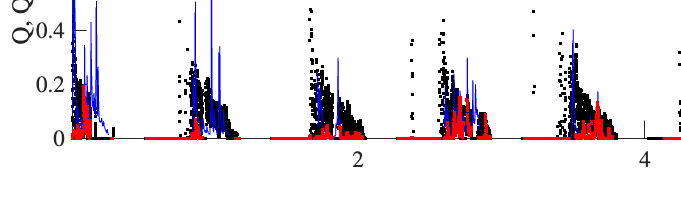

f3 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6500 6.4000]
       Units: 'inches'

  Show all properties


% % %Plot time with discharge and precipitation. This function will change
% % %depending on data format. Please change this function accordingly
% % origdat=char(strcat(originaldata(1)));
% % f1 = figtQP_plot_UK(origdat,workdir,workdirfig,printfig)

cd(workdir)
%Plot ERRA time with real discharge, predicted discharge, and its residual
f3 = figtQQp_plot_dZ(workdir,workdirfig,printfig,2)

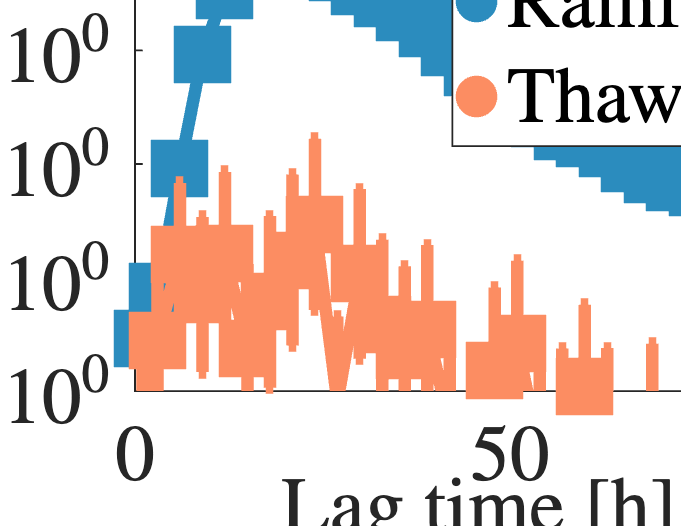

f4 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.8500 7.6000]
       Units: 'inches'

  Show all properties


cd(workdir)
%Plot lagtime with RRD
str = {'Rresults/1hr_simple_RRD.txt'};
f4 = figtRRD_plot_dZ('',workdir,workdirfig,printfig,2,str,{'RRD - rainfall [1/h]', 'RRD - thawing [1/h]'},1)